### Import the dataset

% "C:\Users\Do Thu An\OneDrive\Desktop\Dynamic Macroeconomics\Problem sets\Dynamic-Macroeconomics\PS1_Code\data.csv"
path = strcat("C:\Users\Do Thu An\OneDrive\Desktop\Dynamic Macroeconomics\Problem sets\Dynamic-Macroeconomics\PS1_Code\data.csv")

path = "C:\Users\Do Thu An\OneDrive\Desktop\Dynamic Macroeconomics\Problem sets\Dynamic-Macroeconomics\PS1_Code\data.csv"

main = strcat('C:\Users\Do Thu An\OneDrive\Desktop\Dynamic Macroeconomics\Problem sets\Dynamic-Macroeconomics\PS1_Code\Matlab'); % Project Folder.
cd (strcat(main)) % Set project folder as current working directory.

addpath(genpath(main)) % Add all subfolders in current working directory to path. Note: Make sure file names are unique.
figout = strcat(main,'/output/figures/'); % Folder for figures.

fprintf('The directory is %s \n\n',main)

The directory is C:\Users\Do Thu An\OneDrive\Desktop\Dynamic Macroeconomics\Problem sets\Dynamic-Macroeconomics\PS1_Code\Matlab 



data = readtable(path);

### 5a. Visualize Real Data 

%realdata_plot.plot_economic_data();

disp(data.Properties.VariableNames)

  Columns 1 through 5

    {'Year'}    {'GDP_constant201…'}    {'GDPPerCapita_co…'}    {'GDPGrowthRate___'}    {'FDIInflow_BoP_U…'}

  Columns 6 through 9

    {'GrossFixedCapit…'}    {'GrossCapitalFor…'}    {'GrossFixedCapit…'}    {'FinalConsumptio…'}



### Exploratory data analysis (EDA)

% Extract actual data columns
actual_T= data(:,1);       % Time
actual_k = data(:,6);      % Empirical capital
actual_i = data(:,5);      % Empirical investment
actual_c = data(:,9);      % Empirical consumption
actual_g = data(:,5);      % Empirical government spending

% Load simulated data
sim_time = (1:length(sim.ksim))'; % Time index
sim_k = sim.ksim;    % Simulated capital
sim_i = sim.isim;    % Simulated investment
sim_c = sim.csim;    % Simulated consumption
sim_g = sim.gsim;    % Simulated government spending

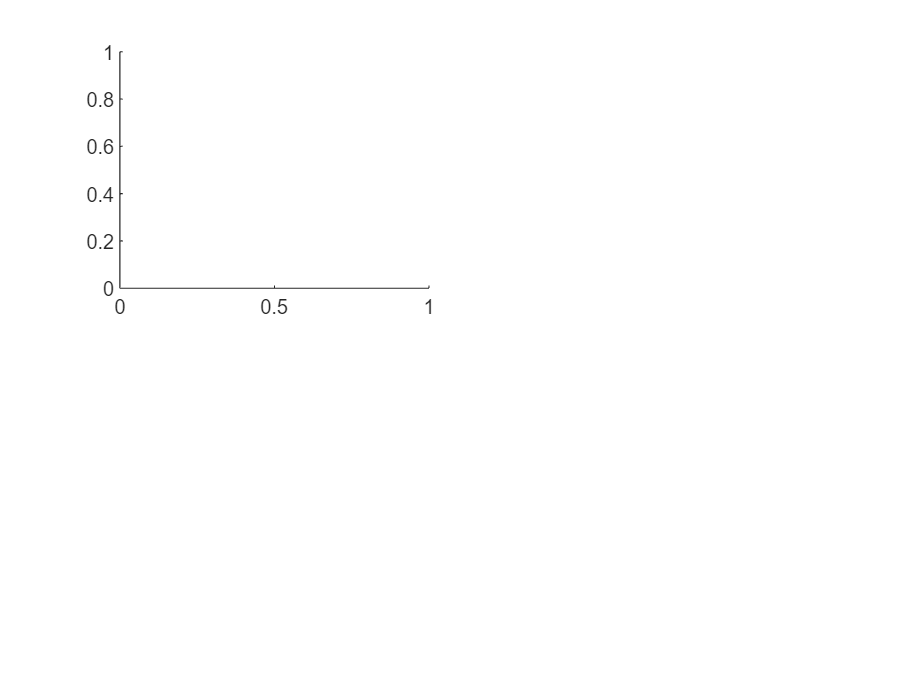

%% Plot Simulated vs Actual Data
figure;

% Capital Stock
subplot(2,2,1);

plot(actual_T, actual_k, 'b', 'LineWidth', 2); hold on;

Error using plot
Invalid subscript for X. A table variable subscript must be a numeric array containing real positive integers, a logical array, a
character vector, a string array, a cell array of character vectors, or a pattern scalar used to match variable names.

plot(sim_time, sim_k, 'r--', 'LineWidth', 2);
title('Capital Stock');
xlabel('Time'); ylabel('Capital');
legend('Actual', 'Simulated');

% Investment
subplot(2,2,2);
plot(actual_T, actual_i, 'b', 'LineWidth', 2); hold on;
plot(sim_time, sim_i, 'r--', 'LineWidth', 2);
title('Investment');
xlabel('Time'); ylabel('Investment');
legend('Actual', 'Simulated');

% Consumption
subplot(2,2,3);
plot(actual_T, actual_c, 'b', 'LineWidth', 2); hold on;
plot(sim_time, sim_c, 'r--', 'LineWidth', 2);
title('Consumption');
xlabel('Time'); ylabel('Consumption');
legend('Actual', 'Simulated');

% Government Spending
subplot(2,2,4);
plot(actual_T, actual_g, 'b', 'LineWidth', 2); hold on;
plot(sim_time, sim_g, 'r--', 'LineWidth', 2);
title('Government Spending');
xlabel('Time'); ylabel('G');
legend('Actual', 'Simulated');

hold off;

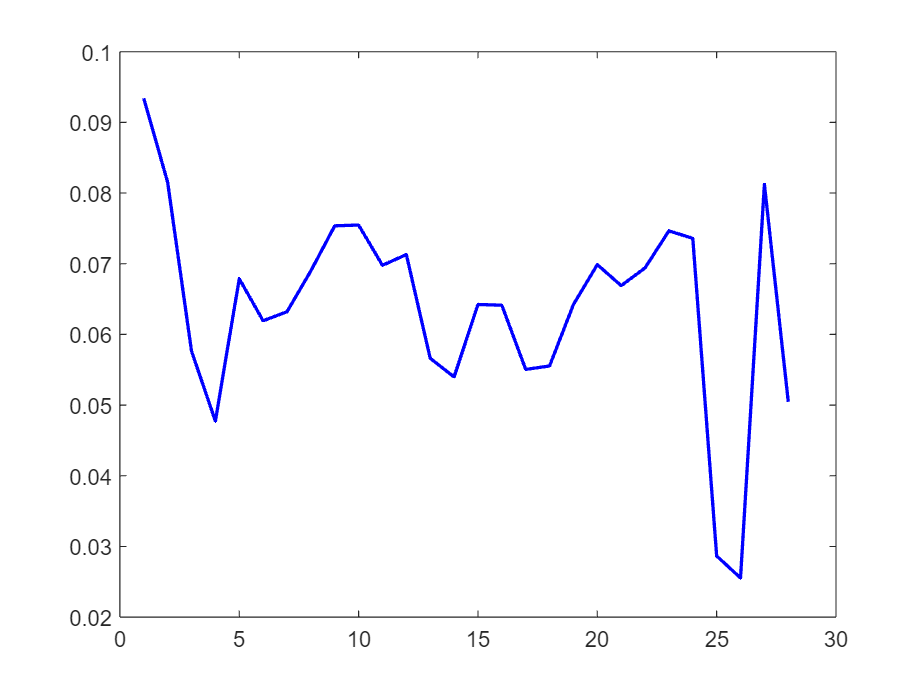

% Extract years from actual data
years_actual = data.Year;

% Define simulated period length
T_sim = 28;  % Assuming your simulation runs for 100 periods
%gdp_growth = str2double(data.("GDP growth rate (%)"));
% Convert years to length format
[actual_T, t_sim] = convert_years(years_actual, T_sim);
% Plot actual vs. simulated GDP Growth
figure;
plot(actual_T, data.GDPGrowthRate___, 'b-', 'LineWidth', 1.5); % Actual data
hold on;

plot(t_sim, sim.ysim, 'r--', 'LineWidth', 1.5); % Simulated data

Error using plot
Vectors must be the same length.

xlabel('Time Periods');
ylabel('GDP Growth (%)');
title('Actual vs. Simulated GDP Growth');
legend('Actual Data', 'Simulated Data');
grid on;

function [t_actual, t_sim] = convert_years(years_actual, T_sim)
    % Function to convert actual years to length of years
    % and align with the simulated data
    
    % Convert actual years to length of years (starting from 1)
    t_actual = 1:length(years_actual);
    
    % Create the time index for simulated data
    t_sim = 1:T_sim;
end